# Actividad 8.1 (SLAM de Lidar) 

   Al principio con los valores genericos evidentemente hacìa muchas colisiones con el laberinto. Entonces de las primeras modificaciones que hice era aumentar el tiempo de muestreo para que tuviera màs informaciòn de su entorno rapidamente y aumentar la velocidad angular respecto a la linear para que de vueltas muy rápido si es que detecta un obstaculo o simplemente necesita hacerlo.  Otra cosa importante que modifiqué fue lidar.scanAngels para que no diera vueltas desde antes


% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:27;        % Time array

% Initial conditions
initPose = [2;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,250);%51
lidar.maxRange = 0.33;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
             2 6;
             4 8;
             8 9;
             7 6;
             7 2;
             9 3;
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.45;%0.5
controller.DesiredLinearVelocity = 0.71; %0.75
controller.MaxAngularVelocity = 18.7

controller =   controllerPurePursuit with properties:

                Waypoints: [7×2 double]
       MaxAngularVelocity: 18.7000
        LookaheadDistance: 0.4500
    DesiredLinearVelocity: 0.7100


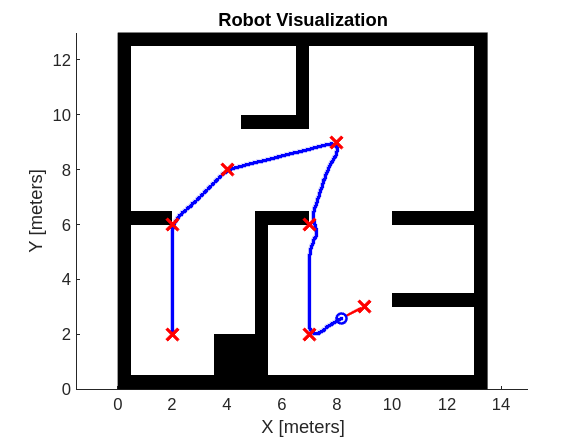


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 90; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.2;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:38;        % Time array

% Initial conditions
initPose = [2;6;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load complexMap.mat

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,pi/2);
lidar.maxRange = 0.7;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
             4 8;
             8 9;
             7 6;
             7 2;
             9 3;
             3.7 4;
             2 2;
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.45;%0.5
controller.DesiredLinearVelocity = 0.7; %0.75
controller.MaxAngularVelocity = 21.2

controller =   controllerPurePursuit with properties:

                Waypoints: [8×2 double]
       MaxAngularVelocity: 21.2000
        LookaheadDistance: 0.4500
    DesiredLinearVelocity: 0.7000


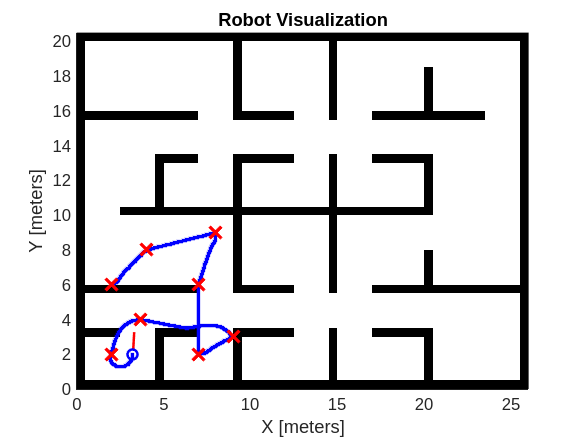


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 90; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.2;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:65;        % Time array

% Initial conditions
initPose = [2;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,pi/2);%51
lidar.maxRange = 0.32;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
             2 2;
             2 4;
             2 8;
             2 10;
             4 10;
             4 8;
             4 4;
             4 2;
             4 4;
             4 8;
             8 10;
             8 8;
             8 4;
             8 2;
             10 2;
             10 4;
             10 8;
             10 10;
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;%0.5
controller.DesiredLinearVelocity = 0.72; %0.75
controller.MaxAngularVelocity = 20.4

controller =   controllerPurePursuit with properties:

                Waypoints: [19×2 double]
       MaxAngularVelocity: 20.4000
        LookaheadDistance: 0.5000
    DesiredLinearVelocity: 0.7200


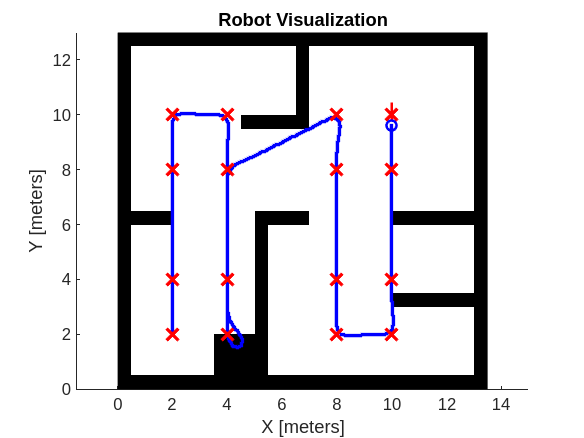


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 90; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.2;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.03;              % Sample time [s]
tVec = 0:sampleTime:38;        % Time array

% Initial conditions
initPose = [1;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,45);%51
lidar.maxRange = 2.56;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
             2 10;
             11 8;
             8 2;
             7.2 8.5;
             1 2;
            ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.15;%0.5
controller.DesiredLinearVelocity = 1.3; %0.75
controller.MaxAngularVelocity = 53.3

controller =   controllerPurePursuit with properties:

                Waypoints: [6×2 double]
       MaxAngularVelocity: 53.3000
        LookaheadDistance: 0.1500
    DesiredLinearVelocity: 1.3000


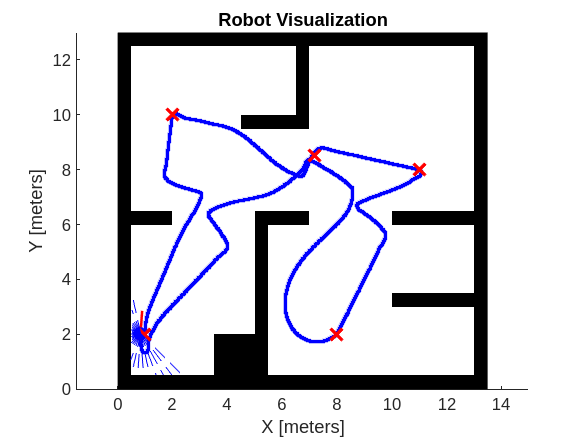


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.1 3]; %0.05 3
vfh.NumAngularSectors = 90; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    
end

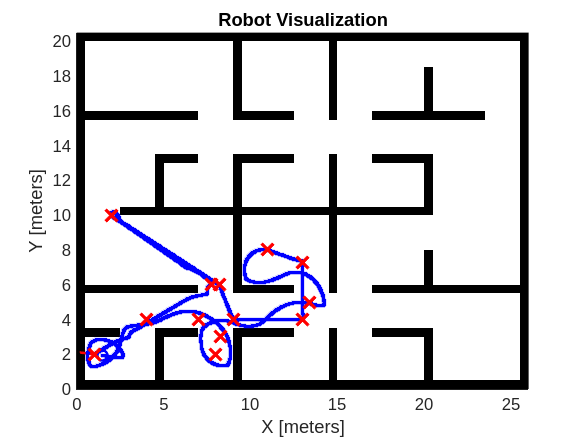

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.01;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.02;              % Sample time [s]
tVec = 0:sampleTime:50;        % Time array

% Initial conditions
initPose = [1;2;pi/5];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load complexMap.mat

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,63);%51
lidar.maxRange = 0.45;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
            
             7.75 6;
             2 10;
             8.2 6;
             9 4;
             13 4;
             13,7.3;
             11 8;
             13.4,5;
             8.3 3;
             8 2;
             7 4;
             4 4
             1 2;
            ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.14;%0.5
controller.DesiredLinearVelocity = 1.4; %0.75
controller.MaxAngularVelocity = 22;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.1 3]; %0.05 3
vfh.NumAngularSectors = 90; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end